% define constraints
n_stadiums = 10;
n_training = 68;
n_teams = 24;
n_games = 36;
capacity = 0.968834;
capacities = [90652,73952,62322,61000,52679,52305,52190,52032,51711,34500];
total_fans = 3000000;
clf
node_labels = {'1 Wembley', '2 Principality', '3 Spurs', '4 Etihad', '5 Everton',...
    '6 St James','7 Villa','8 Hampden','9 Aviva Dublin','10 Casement Belfast'};

The problem will be set up as follows:

- place stadiums in respective locations using lat/lon

- create graph of stadia as nodes with distances between them

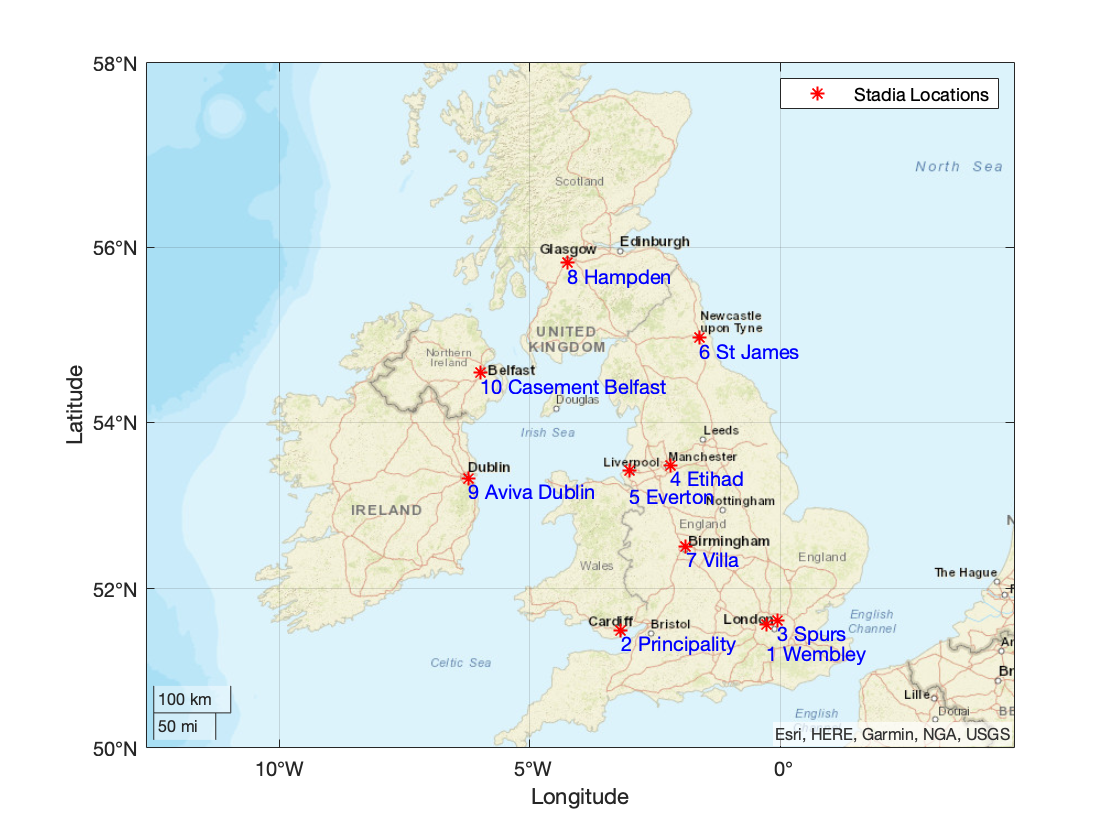

r1 = [50 58];
r2 = [-10 2];
stadium_lat = [51.5560247, 51.4782118,51.6037197, 53.4831666, 53.4249637, 54.9755533, 52.5091149,55.8258715, 53.3337262, 54.5732222];
stadium_lon = [-0.2821926, -3.185209, -0.0685559, -2.2029485, -3.0215617, -1.6242033, -1.8873577, -4.2545474, -6.2324211 ,-5.9865014];
geoplot(stadium_lat, stadium_lon,'*', LineWidth=1, Color='r');
legend('Stadia Locations')
stadium_lat_plot = stadium_lat- 0.15;
stadium_lat_plot(1)=stadium_lat_plot(1)-0.2;
stadium_lat_plot(5)=stadium_lat_plot(5)-0.15;
% Add labels to each point
for i = 1:length(stadium_lat)
    
    text(stadium_lat_plot(i), stadium_lon(i), node_labels{i}, 'Color', 'b', 'FontSize', 10);
end
geolimits(r1,r2)
geobasemap streets

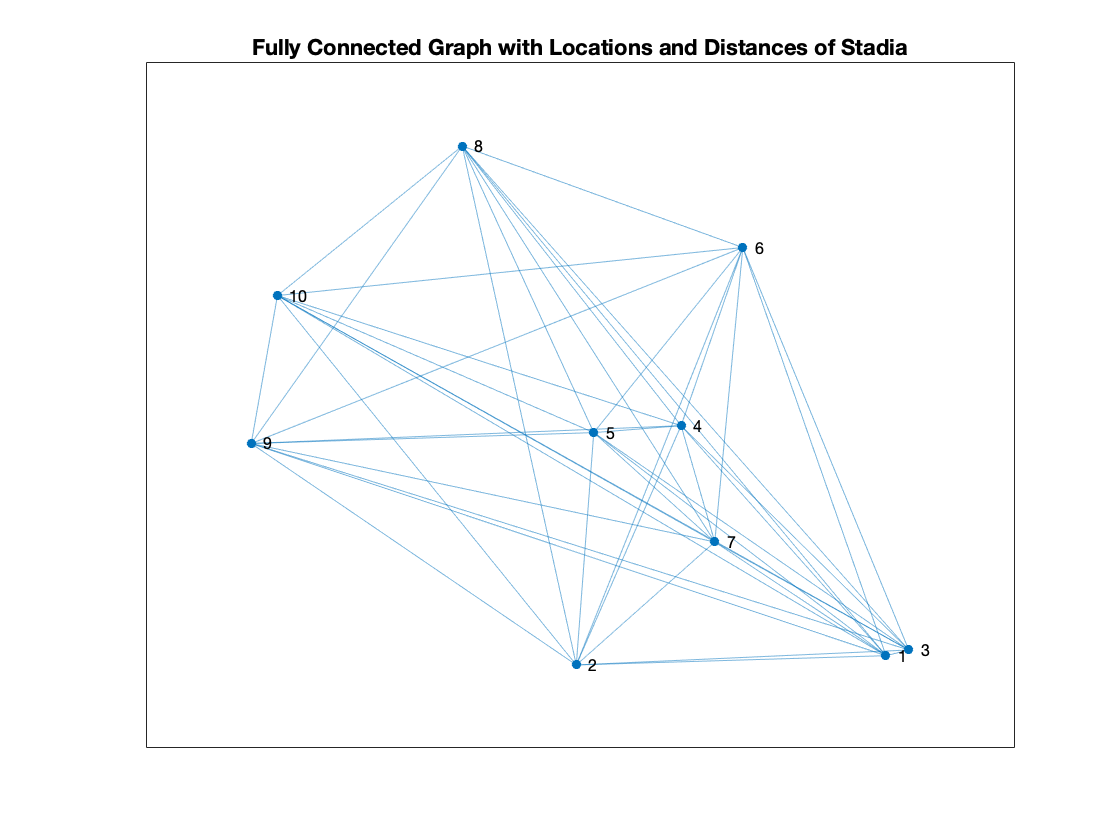

% Now calculate each pairwise distance between the stadia
distances = zeros(n_stadiums,n_stadiums);
for stadium_a = 1 : 10
    for stadium_b = 1:10
        % calculate distance between the stadia
        dist = distance(stadium_lat(stadium_a), stadium_lon(stadium_a), stadium_lat(stadium_b), stadium_lon(stadium_b),[],'degrees');
        distances(stadium_a, stadium_b) = dist;
    end
end
distances_km = deg2km(distances);
% create a fully connected graph using distances as weights
x_plot=stadium_lon;
y_plot=stadium_lat;
n = length(x_plot);
g = graph(ones(n,n), 'omitselfloops');      % complete graph
g.Edges.Weight = zeros(size(g.Edges.EndNodes, 1),1);
% edge distance

for i=1:size(g.Edges, 1)
    g.Edges.Weight(i) = deg2km(norm([x_plot(g.Edges.EndNodes(i,2))-x_plot(g.Edges.EndNodes(i,1)) ...
        y_plot(g.Edges.EndNodes(i,2))-y_plot(g.Edges.EndNodes(i,1))]));
end
h = plot(g);%,'EdgeLabel',g.Edges.Weight);
h.XData = x_plot;
h.YData = y_plot;
title('Fully Connected Graph with Locations and Distances of Stadia')

Continue setting up problem:

- The goal is to distribute games such that travel is minimised

- There are 24 teams and a total 51 matches

- Each game has to take place at a node and all fans have to travel there

- Assume initially that each team has equal fan base

- Start by randomly assigning 2 teams to each of 36 group stage games

% eq_n_fans = total_fans / n_teams;
% teams represented by grid of rows = groups a-f, columns = teams
teams = zeros(6,4);
ii = 1;
for i = 1:6 % number of groups
    for j = 1:4 % number of teams
        % assign a unique value to each team
        teams(i,j) = ii;
        ii = ii +1;
    end
end

% create an array of all games needed in the group stage - minimise the
% movement of fans ie minimise the movement of teams.
games = [];
for i = 1:6
    P = nchoosek(teams(i,:),2);
    games = [games; P]; % all games needed to be played
end
games'

ans =      1     1     1     2     2     3     5     5     5     6     6     7     9     9     9    10    10    11    13    13    13    14    14    15    17    17    17    18    18    19    21    21    21    22    22    23
     2     3     4     3     4     4     6     7     8     7     8     8    10    11    12    11    12    12    14    15    16    15    16    16    18    19    20    19    20    20    22    23    24    23    24    24


Minimisation of total distance:

- Minimising the total distance travelled by all teams by changing which games are played where

- Encouraging a home team to travel more?

Subject to:

- all stadiums must be used

- all games must be played

This will be a global minimisation problem

% objective function where x is just the location for each game
fun = @(x) calculateTotalDistance(x, n_teams, games, distances_km, capacities);
% initial guess can just be random
X0 = randi(10,length(games),1);

% randomly assigned
rand_dist = fun(X0)

rand_dist = 6.0646e+03

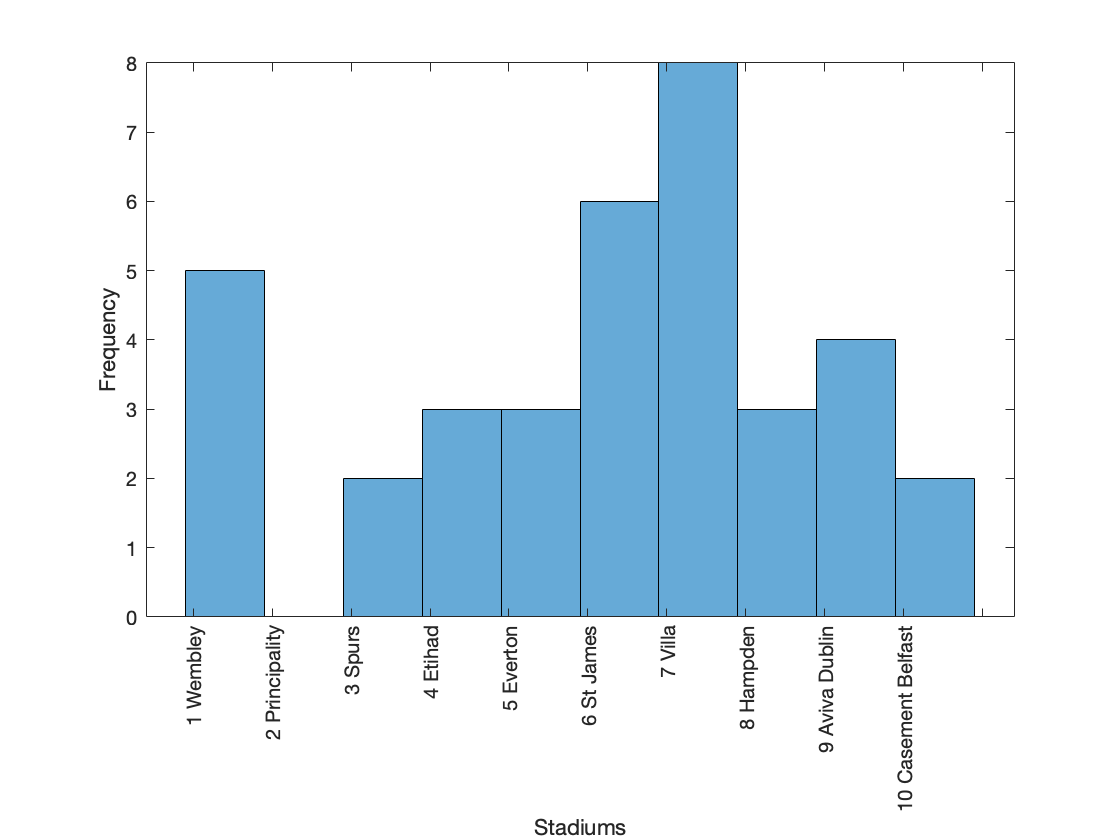

% show histogram of which stadiums used most 
figure;
histogram(X0,10);
d1 = histcounts(X0);
xlabel('Stadiums');
ylabel('Frequency');
xticklabels(node_labels);
xtickangle(90);

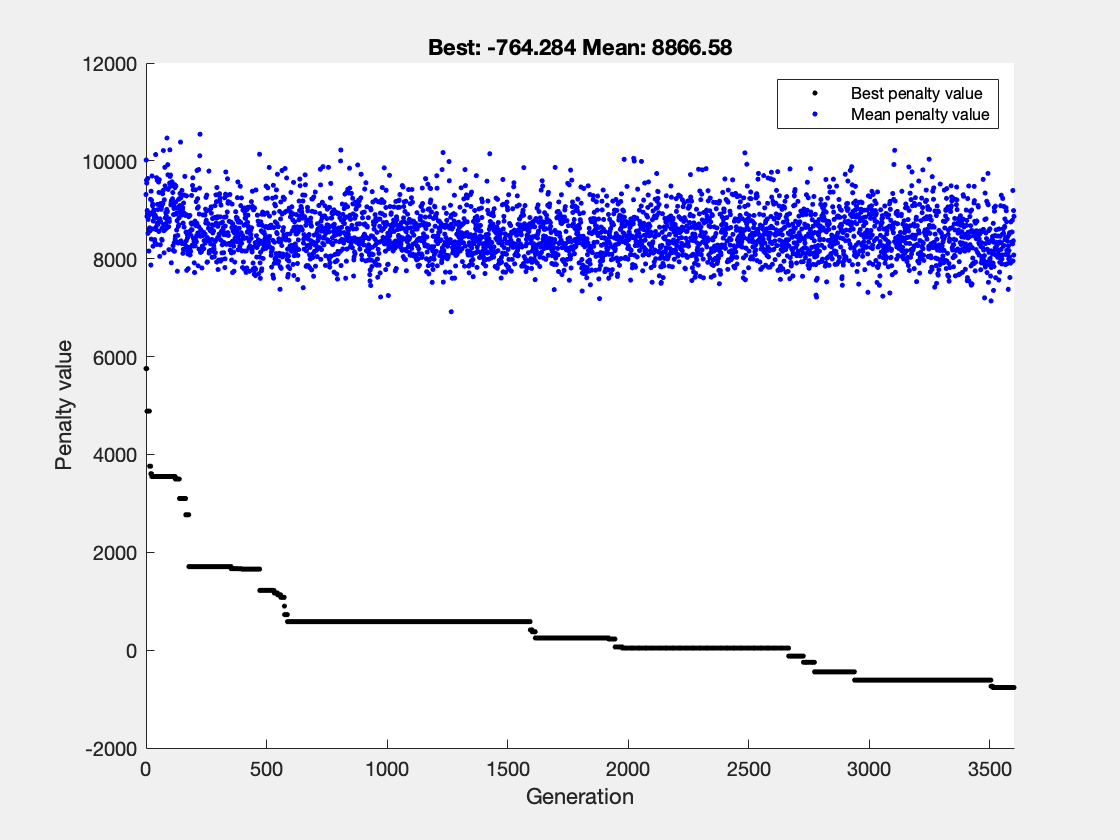

Optimization terminated: maximum number of generations exceeded.


x =      1     9     2     3     3     1     1     1     3     1     1     3     7     4     5     7     5     7     8     8     8     6     6     6     5     5     9     5     9    10     4     4     4     4     5     7


fval = -764.2843

% begin optimisation
LB = ones(length(games),1); 
UB = ones(length(games),1) * 10;

% other possible constraints
% first game (england) at wembley
A = zeros(length(X0),length(X0));
A(1,1) = 1;
b = zeros(length(X0),1);
b(1)=1;

% Nonlinear constraint function - so all stadiums used
NLConstraint = @(x) nonLinearConstraint(x, n_stadiums);

% integer constraints = all
intcon = 1:length(games);
% 'PlotFcn',{@gaplotbestf}
options = optimoptions("ga",'PlotFcn',{@gaplotbestf}, MaxStallGenerations=2000);
[x,fval] = ga(fun, length(X0),A, b, [], [], LB, UB, NLConstraint,intcon, options)

Best order of stadiums = x, can calculate the true cost as follows: (current record 3.0919e+03)

indi_dists'

ans =   740.9417         0         0   15.6859         0         0         0   15.6859  164.9369  127.0416         0  127.0416         0         0         0         0         0  213.1977         0  138.7615         0   54.5875         0  127.0416


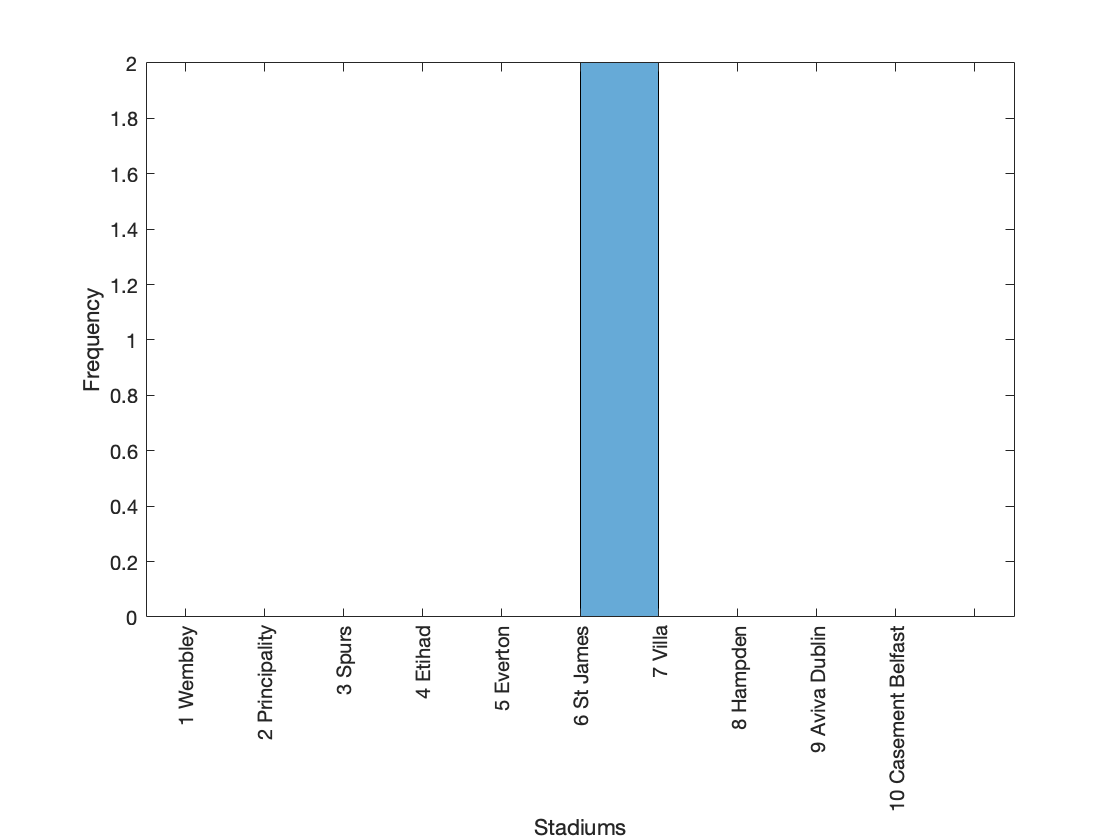

% show histogram of which stadiums used most 
d2 = histcounts(x);
histogram(x,10)
xlabel('Stadiums');
ylabel('Frequency');
xticklabels(node_labels);
xtickangle(90);

figure;
bar([d1;d2]', "grouped")

Error using vertcat
Dimensions of arrays being
concatenated are not consistent.

xlabel('Stadiums');
ylabel('Frequency');
xticklabels(node_labels);
legend('Random assignment','Optimised')
xtickangle(90);
movement_matrix = [x;games'];
% calculate true distance and true team distance
[total_dist, indi_dists, locations] = true_distances(movement_matrix,n_teams,distances_km);
total_dist, indi_dists'
reduction_in_dist = rand_dist - total_dist

The total_dist will be the total distance that each team has to travel during this stage of the tournament, while the indi_dists are the individual distances travelled by each team (1-24) in the tournament. Note that team 1 currently denotes England and as such has been optimised to travel the GREATEST distance (This is so more fans around the UK can see the home team play and therefore have a better *fan experience*) and start at Wembley (as the first game of the tournament) while the other teams aim to travel the least, and their distances minimised. 

% Look at most common journeys 
unique_journeys = common_pairs(locations) % row 1,2 is pair, row 3 is occurence
% how does it relate to the actual locations
node_labels = {'1 Wembley', '2 Principality', '3 Spurs', '4 Etihad', '5 Everton',...
    '6 St James','7 Villa','8 Hampden','9 Aviva Dublin','10 Casement Belfast'};
h = plot(g);%,'EdgeLabel',g.Edges.Weight);
h.XData = x_plot;
h.YData = y_plot;
% Set node labels
h.NodeLabel = node_labels;
title('Fully Connected Graph with Locations and Distances of Stadia')
% most common pairing
[~,idx] = max(unique_journeys(3,:));
stad1 = node_labels(unique_journeys(1,idx))
stad2 = node_labels(unique_journeys(2,idx))
figure;
grid on;
% histogram_counts = histcounts(unique_journeys(1:2,:), length(unique_journeys));
bar(unique_journeys(3,:));
xlabel('Stadium Pair');
ylabel('Frequency of Travel');
% Set x-axis ticks
xticks(1:length(unique_journeys));
xticklabels(cellstr(num2str(unique_journeys(1:2,:)')));
xtickangle(45);  % Rotate x-axis labels for better visibility
text(3,4,node_labels)

Functions

function [C, Ceq] = nonLinearConstraint(x, n_stadiums)
    % Nonlinear constraint
    % minimise so c(x) <= 0
    
    Ceq = [];
    % min number of games = 1
    % max number of games at a stadium = 4
    % C = mean(histcounts(x)) - 4;
    c1 = - length(unique(x)) + n_stadiums;
    c2 =  max(histcounts(x)) - 6;
    C = [c1;c2];
    
end

function objective = calculateTotalDistance(x, n_teams, games, distances_km, capacities)

    % Calculate total capacity using vectorized operations
    total_capacity = sum(capacities(x));

    % Normalize total capacity
    norm_total_capacity = total_capacity / 36;

    % Calculate the total distance based on the binary vector x
    % indicating which games are played at each stadium
    
    n_games = length(games);
    movement_matrix = zeros(3,n_games);
    for game = 1:n_games
        % assign a random stadium to each game
        movement_matrix(1,game) = round(x(game));
        % place the teams that would play there
        movement_matrix(2,game) = games(game,1);
        movement_matrix(3,game) = games(game,2);
    end
    
    % Calculate the total distance moved for each team
    prev_locations = zeros(1,n_teams);
    total_teams_dist = 0;
    indi_team_dist = zeros(n_teams,1);

    home_team_a = 1;
    home_team_b = 1;
    
    for game = 1:n_games
    % check what location the team was at 
        % team A
        prev_i_a = prev_locations(movement_matrix(2,game));
        current_i_a = movement_matrix(1,game);
        % team B
        prev_i_b = prev_locations(movement_matrix(3,game));
        current_i_b = movement_matrix(1,game);

        % make england (team 1) visit more stadiums - the minimum cost if -
        % if team==1
        if movement_matrix(2,game) == 1
            home_team_a = -1;
        elseif movement_matrix(3,game) == 1
            home_team_b = -1;
        else
            home_team_a = 1;
            home_team_b = 1;
        end
            
        if prev_i_a ~= current_i_a
            % calculate the distance moved
            if prev_i_a ~= 0
                dist_moved = distances_km(prev_i_a,current_i_a);
            else
                dist_moved = 0;
            end
            % update previous loc
            prev_locations(movement_matrix(2,game)) = current_i_a;
            total_teams_dist = total_teams_dist + home_team_a*dist_moved;
            indi_team_dist(movement_matrix(2,game)) = indi_team_dist(movement_matrix(2,game)) + dist_moved;
        end
    
        % team B
        if prev_i_b ~= current_i_b
            % calculate the distance moved
            
            if prev_i_b ~= 0
                dist_moved = distances_km(prev_i_b,current_i_b);
            else
                dist_moved = 0;
            end
            % update previous loc
            prev_locations(movement_matrix(3,game)) = current_i_b;
            total_teams_dist = total_teams_dist + home_team_b*dist_moved;
            indi_team_dist(movement_matrix(3,game)) = indi_team_dist(movement_matrix(3,game)) + dist_moved;
        end
    end
    
    % Return the total distance as the objective value
    total_distance = total_teams_dist;
    objective = total_distance - norm_total_capacity/20;
end

function [total_distance, indi_distance, locations] = true_distances(movement_matrix, n_teams, distances_km)
    % Calculate the total distance based on the binary vector x
    % indicating which games are played at each stadium
    
    n_games = length(movement_matrix);
    
    % Calculate the total distance moved for each team
    prev_locations = zeros(n_games,n_teams);
    total_teams_dist = 0;
    indi_team_dist = zeros(n_teams,1);
    
    for game = 1:n_games
    % check what location the team was at 

        if game == 1
            prev_i_a = 0;
            prev_i_b = 0;
        else
            prev_i_a = prev_locations(game-1,movement_matrix(2,game));
            prev_i_b = prev_locations(game-1,movement_matrix(3,game));
        end
        current_i_a = movement_matrix(1,game);
        current_i_b = movement_matrix(1,game);
            
        if prev_i_a ~= current_i_a
            % calculate the distance moved
            if prev_i_a ~= 0
                dist_moved = distances_km(prev_i_a,current_i_a);
            else
                dist_moved = 0;
            end
            % update previous loc
            prev_locations(game,movement_matrix(2,game)) = current_i_a;
            total_teams_dist = total_teams_dist + dist_moved;
            indi_team_dist(movement_matrix(2,game)) = indi_team_dist(movement_matrix(2,game)) + dist_moved;
        end
    
        % team B
        if prev_i_b ~= current_i_b
            % calculate the distance moved
            
            if prev_i_b ~= 0
                dist_moved = distances_km(prev_i_b,current_i_b);
            else
                dist_moved = 0;
            end
            % update previous loc
            prev_locations(game,movement_matrix(3,game)) = current_i_b;
            total_teams_dist = total_teams_dist + dist_moved;
            indi_team_dist(movement_matrix(3,game)) = indi_team_dist(movement_matrix(3,game)) + dist_moved;
        end
    end
    
    % Return the total distance as the objective value
    total_distance = total_teams_dist;
    indi_distance = indi_team_dist;
    locations = prev_locations;
end

function unique_pairs = common_pairs(locations)

    pairs = [];

    % Iterate through each column
    for col = 1:size(locations, 2)
        % Extract non-zero values
        non_zero = locations(:, col);
        non_zero = non_zero(non_zero ~= 0);

        % Identify every pair
        if numel(non_zero) > 1
            for i = 1:numel(non_zero)-1
                a = non_zero(i);
                b = non_zero(i+1);
                if a ~= b
                    pairs = [pairs; [a, b]];
                end
            end
        end
    end

    % Count occurrences of each unique pair
    [uniquePairs, ~, idx] = unique(sort(pairs, 2), 'rows');
    occurrences = accumarray(idx, 1);
    unique_pairs = [uniquePairs';occurrences']; % row 1,2 is pair, row 3 is occurence
end


function cost = travel_cost(number_fans, distance)
    cost = number_fans * distance;
end


